# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_sgmhc.mlx
    -----------------
    This code solves the stochastic growth model with human capital accumulation using value function iteration.

%}

## Model: Stochastic Growth Model with Human Capital Accumulation.

The social planner's problem is


$$\begin{array}{r l}
\underset{\{c_t\}_{t=1}^{\infty},\{k_{t+1}\}_{t=1}^{\infty},\{h_{t+1}\}_{t=1}^{\infty}}{\text{max }} \mathbb{E}_0\left(U\right) &= \mathbb{E}_0\sum_{t=1}^\infty \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma} \ , \\
\text{s.t.} y_t &= c_t+i^k_t \ ,\\
y_t &= A_t k_t^{\alpha}(u_th_t)^{\gamma}  \ , \\
\text{log}(A_{t+1}) &= \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \, \\
k_{t+1} &= (1-\delta_k)k_t + i^k_t \ ,\\
h_{t+1} &= (1-\delta_h)h_t + (1-u_t)h_t \ , \\
c_t &> 0 \ , \\
k_t &> 0 \ ,
\end{array}
$$


where $|\rho| < 1$, $\epsilon_{t+1}\sim\mathcal{N}(0,\sigma^2_{\epsilon})$, $\alpha+\gamma=1$, and the constraints hold for $t = 1, 2, ..., .$ Assume that the labor force is normalized to 1 and    does not grow. The time endowment is normalized to 1. Human capital accumulates and can be invested in much like physical capital, and is used in production. The difference the two is that a fraction of the time endowment, $1-u_t$, is used to invest in human capital instead of production. The productivity term, $A_t$, is a stationary AR(1) process in logs and expectations are taken over these.

## Recursive Formulation.

The recursive formulation, combining the constraints into one, is


$$\begin{array}{r l l} 
V_t(k_t,A_t,h_t) &= \underset{c_t, k_{t+1},h_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1},h_{t+1})\right] \ , \\
\text{s.t. } \ \ \ A_tk_t^{\alpha}(u_th_t)^{\gamma} &=  c_t + k_{t+1} - (1-\delta_k)k_t \ , \\ 
h_{t+1} &= (1-\delta_h)h_t + (1-u_t)h_t \ , \\
\text{log}(A_{t+1}) &= \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \ , \\
c_t &> 0 \ , \\
k_t &> 0 \ .
\end{array}$$


Because of the productivity shocks, the state space has now expanded to include this. Substituting the combined constraint into the utility function gives


$$\begin{array}{r l}
V_t(k_t,A_t,h_t) &= \underset{k_{t+1},h_{t+1}}{\text{max}}\frac{\left[A_tk_t^{\alpha}\left(2h_t-\delta_th_t-h_{t+1}\right)^{\gamma}+(1-\delta_k)k_t-k_{t+1}\right]^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1},h_{t+1})\right] \ , \\
\text{s.t.} \ \text{log}(A_{t+1}) &= \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \ , \\
k_t &> 0 \ ,
\end{array}$$


simplifying the problem.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('C:\Users\USER\Documents\GitHub\Problem_set_1_Dynamic_Macro\Question 5'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\USER\Documents\GitHub\Problem_set_1_Dynamic_Macro\Question 5 



## Set the parameters and generate the state space.

Calls: model.m.

We cannot directly compute the steady state capital as before because of human capital, so we set an exogenous grid for $k_t$ and $h_t$.

par = qmodel.setup; % Set parameters.
par = qmodel.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration.

Calls: solve.m, and model.m.

As in the deterministic case, we will solve the model using value function iteration using 


$$V(k_t) = \frac{1}{1-\beta} \frac{\left[A_Tk_T^{\alpha}\left(2h_T-\delta_th_T\right)^{\gamma}+(1-\delta_k)k_T\right]^{1-\sigma}}{1-\sigma} \ ,$$


as a guess. This is the optimal solution in the finite-horizon case: consume everything in the last period.

t = cputime;
sol = qsolve.grow(par); % Solve the model using Value Function Iteration.


------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.

Converged in 380 iterations.

------------End of Value Function Iteration.------------



fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 135.1719 seconds.


## Simulate the model and plot the model functions and time series.

Calls: simulate.m and my_graph.m.

This section simulates the stochastic growth model with human capital. The graphs below plot the policy function for the lowest level of productivity. Note that human capital investment is chosen so that it offsets the depreciation of human capital. Physical capital, on the other hand, may respond to very large shocks to productivity.

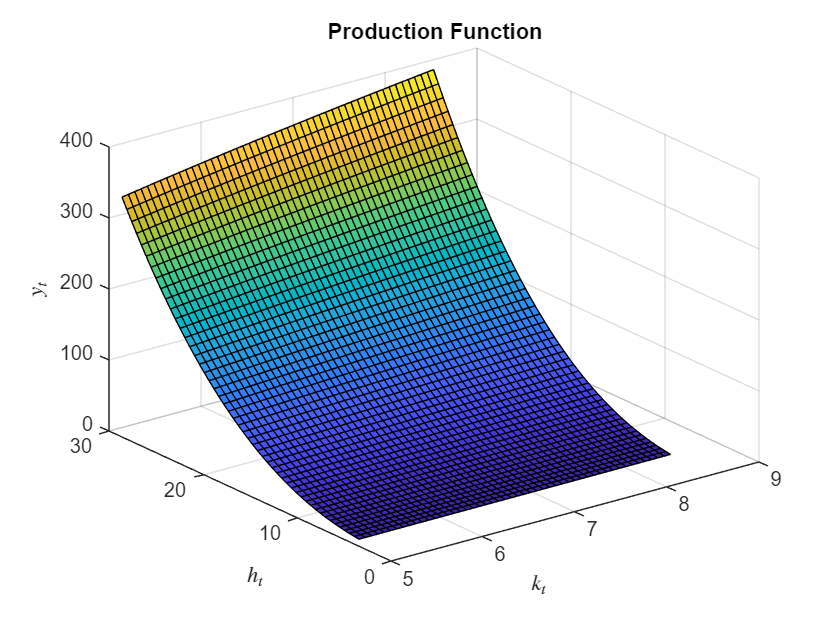

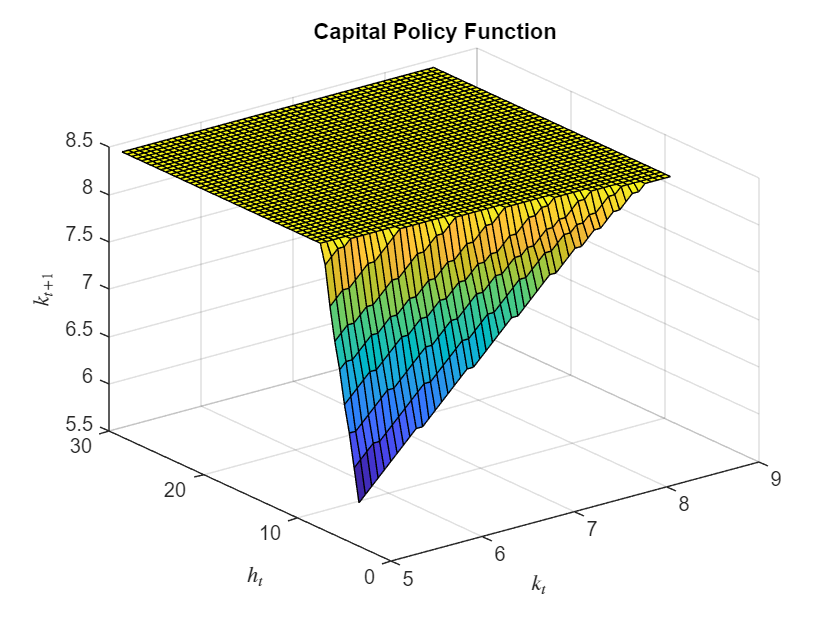

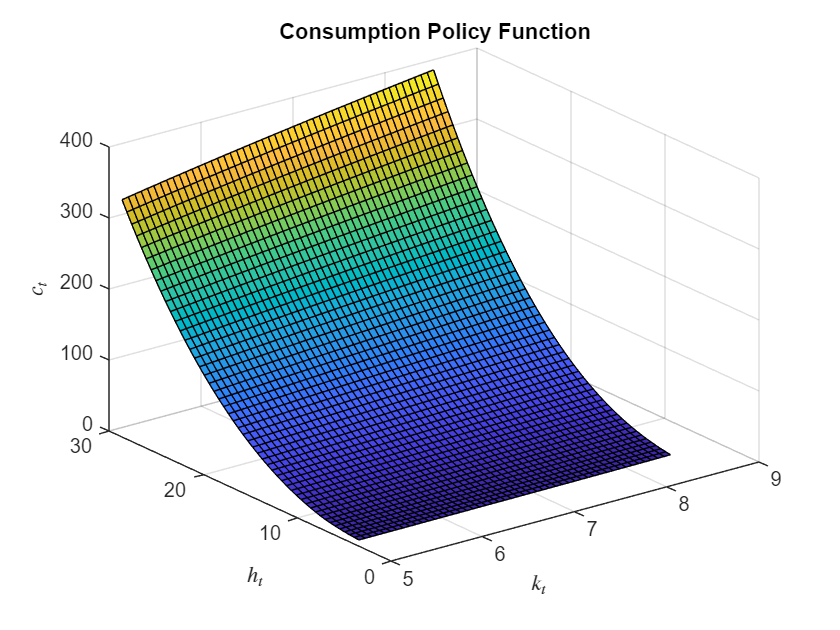

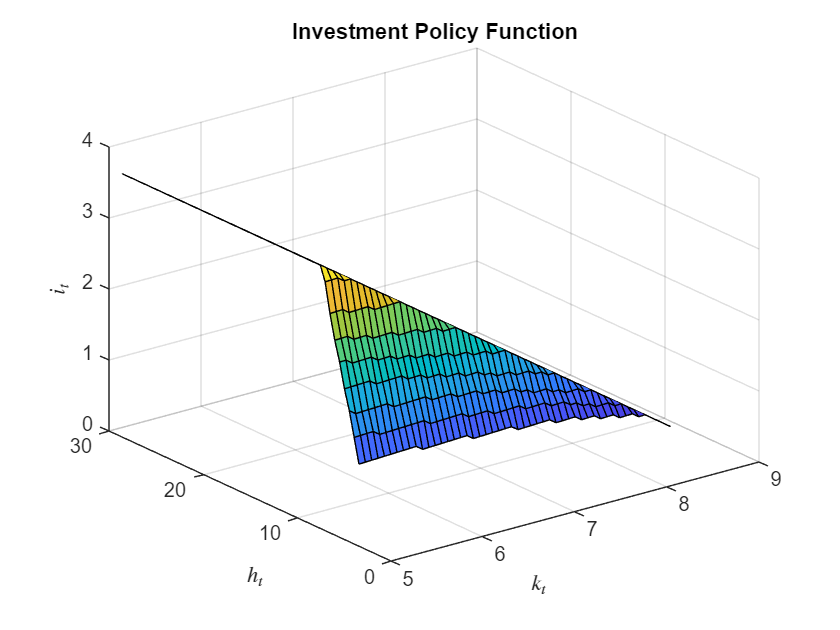

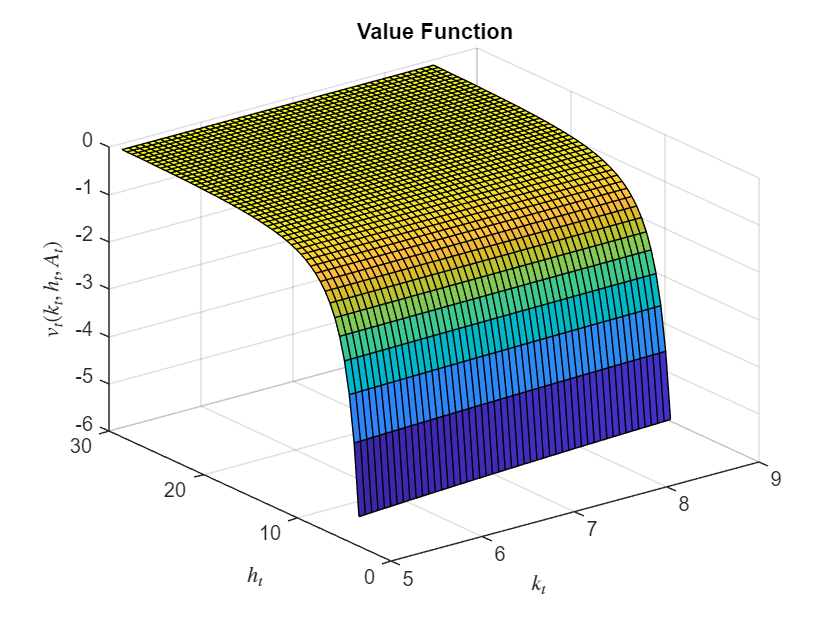

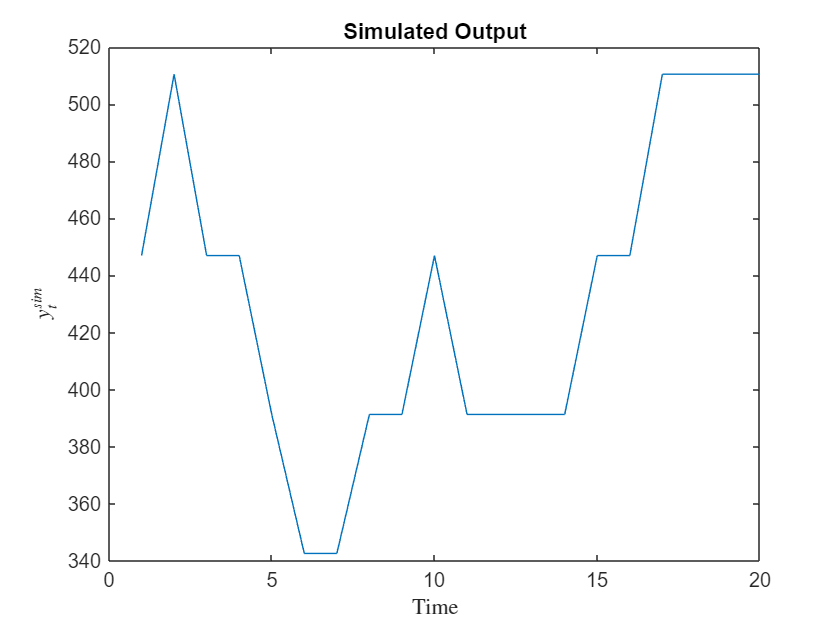

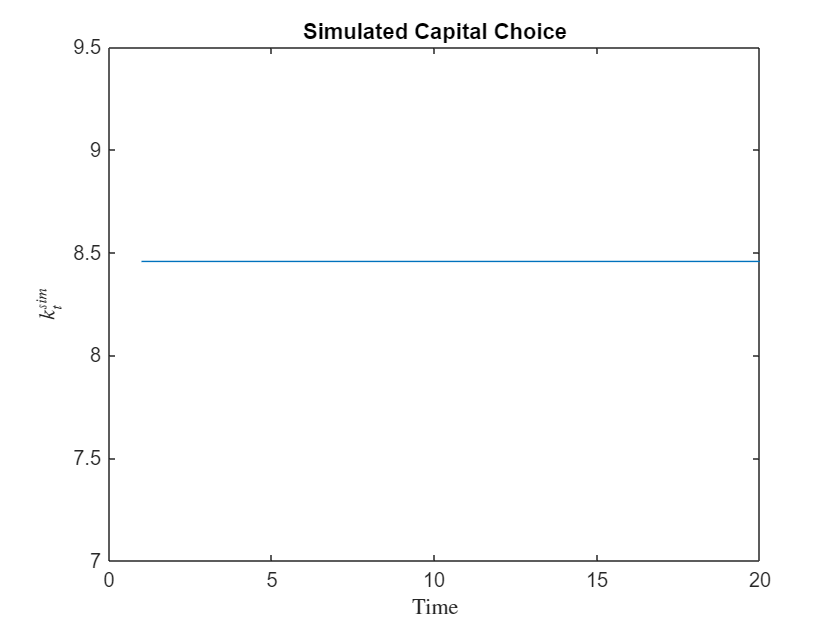

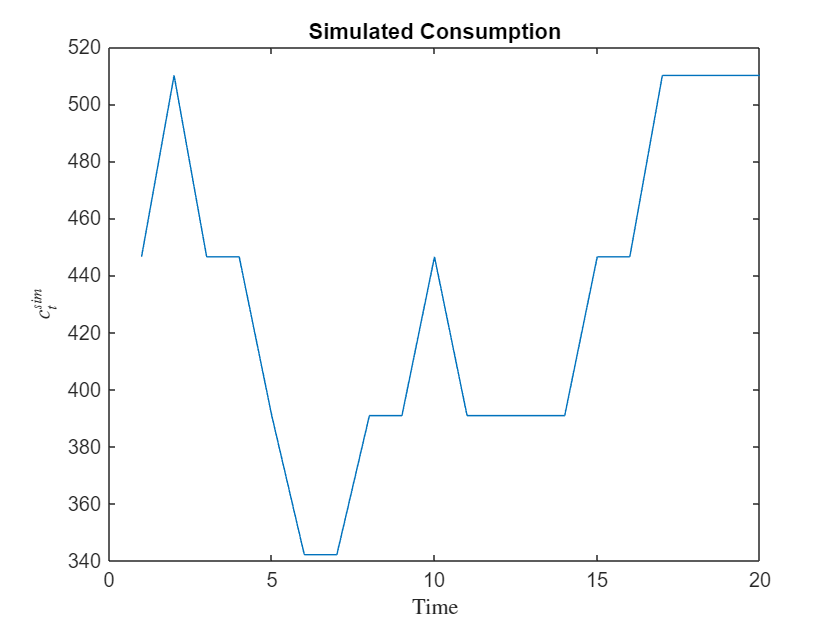

sim = qsimulate.grow(par,sol); % Simulate the model.
qmy_graph.plot_policy(par,sol,sim) % Plot the model functions and time series.